# TI单芯片毫米波雷达IWR6843ISK使用串口采集原始数据

## 1.雷达参数设置

- 发射天线：3个

- 接收天线：4个

- 一帧数据的chirp数：96个（两个脉冲交替各发射96次）

- ADC采样点数：128个

- ADC位数：16bit（两个字节组成一个十进制数）

- 采样形式：IQ正交采样（两个十进制数组成一个复数，I+jQ）;

- ADC采样率为：5.5Msps。

具体在CFG文件中，如下图所示：

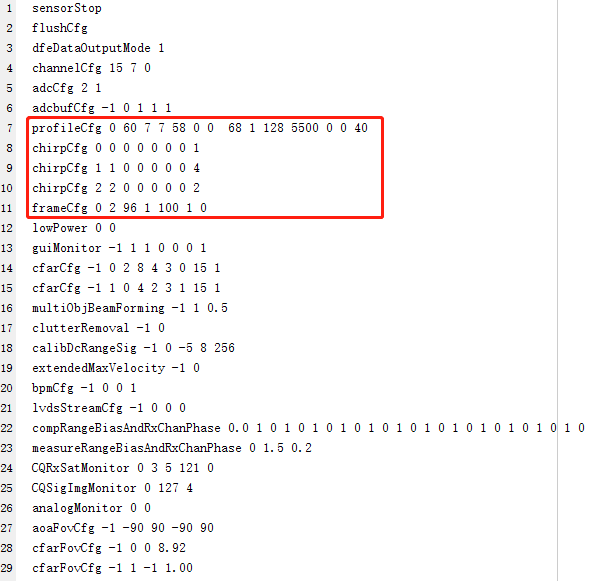

2.结果展示

具体的硬件、软件环境、操作步骤、数据结构等内容已经在《[TI单芯片毫米波雷达IWR1642使用串口采集原始数据教程（附MATLAB代码、bin文件和数据）](https://link.zhihu.com/?target=http%3A//mp.weixin.qq.com/s%3F__biz%3DMzkxMTMwMTg4Mg%3D%3D%26mid%3D2247484072%26idx%3D1%26sn%3D8b5ac0aa928c5b7108d85eda9a937ec1%26chksm%3Dc11f0f3df668862b4cabac8ea710fd7c463c86acebfd139f9eeda15809a7e850e6edc545484a%26scene%3D21%23wechat_redirect)》一文进行了详细的介绍，本文不进行重复性地概述了，读者可结合前一篇内容进行学习。

（1）实虚部波形

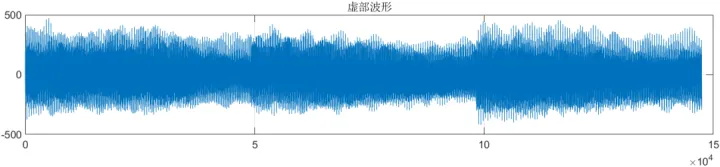

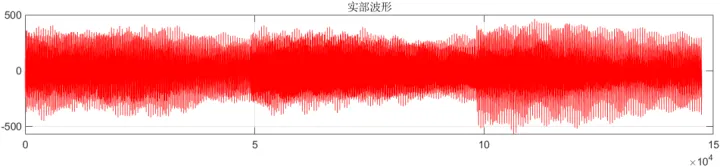

（2）距离维FFT结果

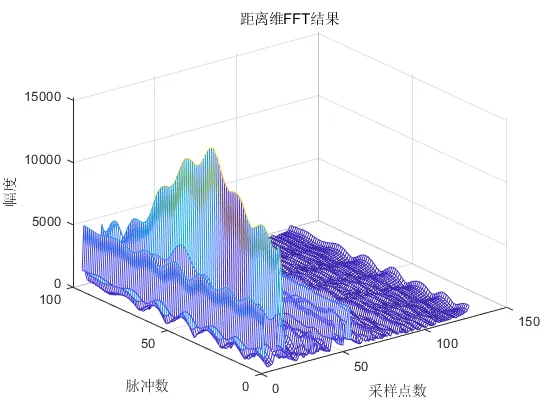

（3）速度维FFT结果

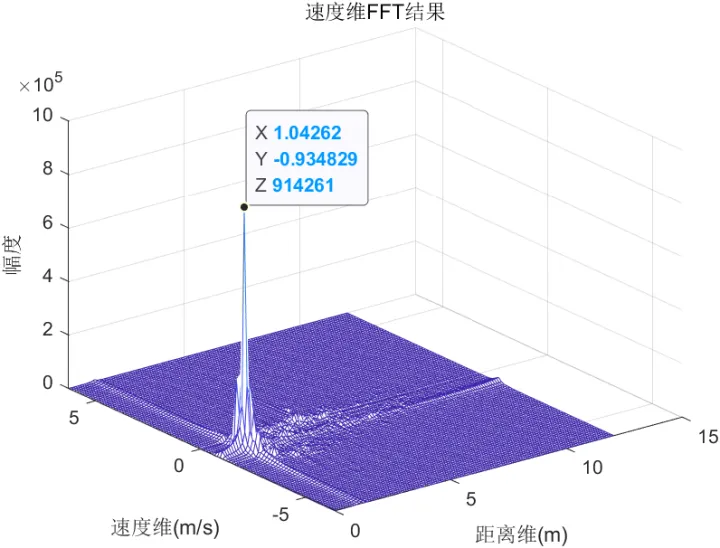

（4）角度估计结果

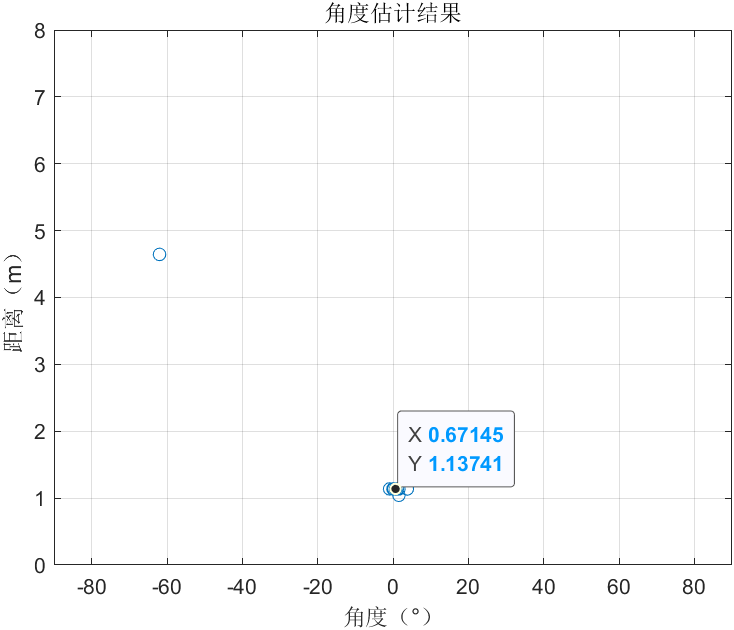

本文所采集的数据是一个人在1米处靠近雷达运动（目标靠近雷达速度为负），目标位于了雷达法线位置，从角度估计的结果来看，基本符合实际情况。

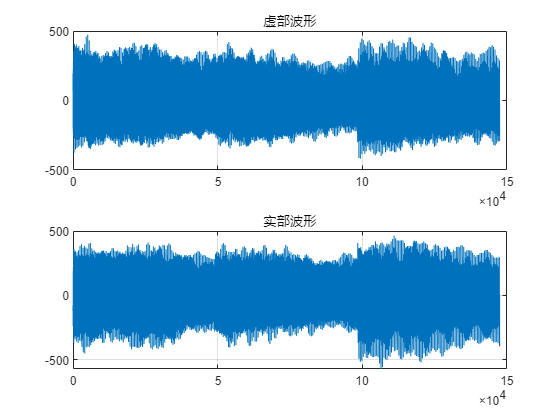

%% 作者：调皮连续波
%% 公众号：调皮的连续波
%% 2022年4月
clc;
close all;
clear all;

%% IWR6843ISK雷达参数
Tx_Number = 3;%发射天线
Rx_Number = 4;%接收天线
Range_Number = 128; % 距离点数（每个脉冲128个点）
Doppler_Number = 96;% 多普勒点数(总共96个重复脉冲数)

%% 雷达参数
global Params;
Params.NChirp  = Doppler_Number;       %1帧数据的chirp个数
Params.NChan   = Rx_Number;                     %RxAn数,ADC通道数
Params.NSample = Range_Number;        %每个chirp ADC采样数
Params.Fs = 5.5e6;                    %采样频率
Params.c = 3.0e8;                     %光速
Params.startFreq = 60e9;              %起始频率 
Params.freqSlope = 68e12;             %chirp的斜率
Params.bandwidth = 3.165e9;                % 真实带宽
Params.lambda=Params.c/Params.startFreq;   % 雷达信号波长
Params.Tc = 195e-6;                        % chirp周期
global FFT2_mag;
[X,Y] = meshgrid(Params.c*(0:Params.NSample-1)*Params.Fs/2/Params.freqSlope/Params.NSample, ...
    (-Params.NChirp/2:Params.NChirp/2 - 1)*Params.lambda/Params.Tc/Params.NChirp/2);   

%% 下发命令标志  采集数据 1,读取数据 0
loadCfg = 0;  
if(loadCfg)
        delete(instrfind);           % 删除串口
        [controlSerialPort,dataSerialPort] = serial_port(); %% 自动识别串口
       
         % controlSerialPort = 'COM5'; % 预先设定USER COM  %%  手动设定串口
         % dataSerialPort    = 'COM4'; % 预先设定DATA COM    
        configurationFileName_stop ='6843_3T4R_cfg.cfg';             % 雷达停止命令
        cliCfg = readCfg(configurationFileName_stop);          % 配置文件读取

        hDataSerialPort = configureDataSport(dataSerialPort,Tx_Number*Rx_Number*Doppler_Number*Range_Number*2*2);%链接 COM串口
        mmwDemoCliPrompt = char('mmwDemo:/>');
        hControlSerialPort = configureControlPort(controlSerialPort);%链接 COM串口
        
        % Send CLI configuration to IWR68xx
        fprintf('Sending configuration from %s file to IWR68xx ...\n', configurationFileName_stop);
        for k=1:length(cliCfg)
            fprintf(hControlSerialPort, cliCfg{k});
            fprintf('%s\n', cliCfg{k});
            echo = fgetl(hControlSerialPort); % Get an echo of a command
            done = fgetl(hControlSerialPort); % Get "Done" 
            prompt = fread(hControlSerialPort, size(mmwDemoCliPrompt,2)); % Get the prompt back 
        end
        prompt_1= fread(hDataSerialPort, Tx_Number*Rx_Number*Doppler_Number*Range_Number*2*2); % Get the prompt back 
       
       %% 可在此保存数据
        adc_data =  dec2hex(prompt_1,2);
        save adc_data,'adc_data.mat';    %各位同学需要在此 存储数据  并重新命名，如adc_data1或adc_data2。
        Data_dec=(adc_data);             %将16进制转换为10进制
        
        fclose(hControlSerialPort);
        delete(hControlSerialPort);
        fclose(hDataSerialPort);
        delete(hDataSerialPort);        
else
        adc_data =load('adc_data.mat');
        Data_dec=hex2dec(adc_data.adc_data);  %将16进制转换为10进制
end

%% 组合数据
Data_zuhe=zeros(1,Tx_Number*Rx_Number*Doppler_Number*Range_Number*2); %建立计算存储数据的空矩阵
for i=1:1:Tx_Number*Rx_Number*Doppler_Number*Range_Number*2
    Data_zuhe(i) = Data_dec((i-1)*2+1)+Data_dec((i-1)*2+2)*256;
    if(Data_zuhe(i)>32767)   %% 限制幅度
        Data_zuhe(i) = Data_zuhe(i) - 65536;
    end
end

%% 分放数据
ADC_Data=zeros(Tx_Number,Doppler_Number,Rx_Number,Range_Number*2); %建立计算存储数据的空矩阵
for t=1:1:Tx_Number
    for i=1:1:Doppler_Number
        for j=1:1:Rx_Number
            for k=1:1:Range_Number*2
                ADC_Data(t,i,j,k) = Data_zuhe(1,(((t-1)*Doppler_Number+(i-1))*Rx_Number+(j-1))*Range_Number*2+k);
            end
        end
    end
end

%% 打印全部的实虚数据
Re_Data_All=zeros(1,Range_Number*Doppler_Number*Tx_Number*Rx_Number); %建立计算存储数据的空矩阵
Im_Data_All=zeros(1,Range_Number*Doppler_Number*Tx_Number*Rx_Number); %建立计算存储数据的空矩阵

for i=1:1:Tx_Number*Rx_Number*Doppler_Number*Range_Number
    Im_Data_All(1,i) = Data_zuhe(1,(i-1)*2+1);
    Re_Data_All(1,i) = Data_zuhe(1,(i-1)*2+2);
end

%% 原始信号实部、虚部图形绘制 
figure(1)
subplot(2,1,1);
plot(Im_Data_All(1,:));title('虚部波形');grid on;
subplot(2,1,2);
plot(Re_Data_All(1,:));title('实部波形');grid on;

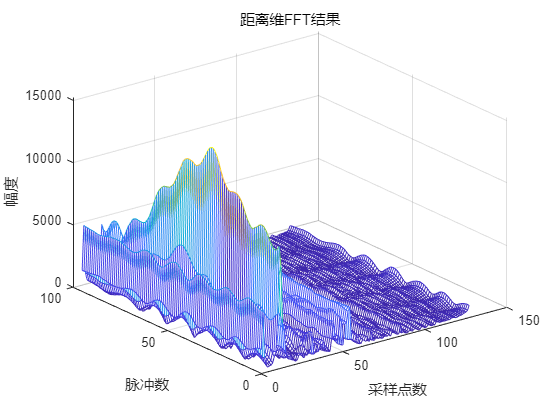


%% 打印分组后的实虚数据 数据结构为：3T4R在TX2组的32个脉冲数据
Re_Data=zeros(Doppler_Number,Range_Number); %建立计算存储数据的空矩阵
Im_Data=zeros(Doppler_Number,Range_Number); %建立计算存储数据的空矩阵

for chirp=1:Doppler_Number %查看所在chirp的数据
    for j=1:1:Tx_Number
        for k=1:1:Rx_Number
            for i=1:1:Range_Number
                Re_Data(chirp,i) = ADC_Data(j,chirp,k,(i-1)*2+2);
                Im_Data(chirp,i) = ADC_Data(j,chirp,k,(i-1)*2+1);
            end
        end 
    end
end

%% 实虚部组合
ReIm_Data = complex(Re_Data,Im_Data);
ReIm_Data_All =complex(Re_Data_All,Im_Data_All);

ind= Range_Number*Doppler_Number*2*Rx_Number;%提取数据长度 TX1和TX3
ReIm_Data_All =ReIm_Data_All(1:ind);%提取TX1和TX3的数据，TX2不要。

ReIm_Data_all1 = zeros(Range_Number,Doppler_Number,4);
ReIm_Data_all2 = zeros(Range_Number,Doppler_Number,4);

for nn=1:Rx_Number % 水平虚拟阵列重组TDM-MIMO 4通道->8通道，垂直阵列只有两根天线
    for mm=1:Doppler_Number       
        ReIm_Data_all1(:,mm,nn) = ReIm_Data_All((nn-1)*Range_Number+ ((mm-1)*4*Range_Number+1):...
            ((mm-1)*4*Range_Number+Range_Number)+(nn-1)*Range_Number  );    

        ReIm_Data_all2(:,mm,nn) = ReIm_Data_All((nn-1)*Range_Number+ind/2+((mm-1)*4*Range_Number+1):...
            ind/2+((mm-1)*4*Range_Number+Range_Number) +(nn-1)*Range_Number );
    end
end

ReIm_Data_All = cat(3,ReIm_Data_all1(:,:,1:4), ReIm_Data_all2(:,:,1:4));

%% 1D FFT
fft1d= zeros(Doppler_Number,Range_Number,Rx_Number*2);
 
for qq =1:2*Rx_Number
    for chirp_fft=1:Doppler_Number 
        fft1d(chirp_fft,:,qq) = fft((ReIm_Data_All(:,chirp_fft,qq)));
    end
end

FFT1_mag=abs(fft1d(:,:,1));%第一个天线通道的1D FFT结果
figure(2);
mesh(FFT1_mag);
xlabel('采样点数');ylabel('脉冲数');zlabel('幅度');
title('距离维FFT结果');

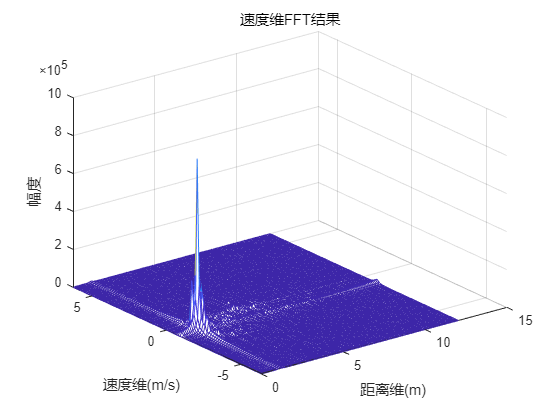


%%  静态杂波滤除 相量均值相消算法
fft1d_jingtai = zeros(Doppler_Number,Range_Number,2*Rx_Number);
for n=1:2*Rx_Number
    avg = sum(fft1d(:,:,n))/Doppler_Number;
    
    for chirp=1:Doppler_Number
        fft1d_jingtai(chirp,:,n) = fft1d(chirp,:,n)-avg;
    end
end
fft1d =fft1d_jingtai;

%%  mti 动目标显示 不推荐使用MTI 两边噪声幅度太大
% fft1d_data =  zeros(Doppler_Number,Range_Number,2*Rx_Number);
% for cc =1:2*Rx_Number
%     for ii =1:Doppler_Number-1
%         fft1d_data (ii,:,cc) = fft1d(ii+1,:,cc)-fft1d(ii,:,cc);
%     end
% end
% fft1d =fft1d_data;
%% 2D FFT 

fft2d= zeros(Doppler_Number,Range_Number,2*Rx_Number);
for kk=1:2*Rx_Number
    for chirp_fft=1:Range_Number 
        fft2d(:,chirp_fft,kk) =fftshift( fft((fft1d(:,chirp_fft,kk))));  
    end
end
fft2d(:,1,:)=0; %直流分量抑制
FFT2_mag=(abs(fft2d(:,:,1)));
figure(3);
mesh(X,Y,FFT2_mag);
xlabel('距离维(m)');ylabel('速度维(m/s)');zlabel('幅度');
title('速度维FFT结果');

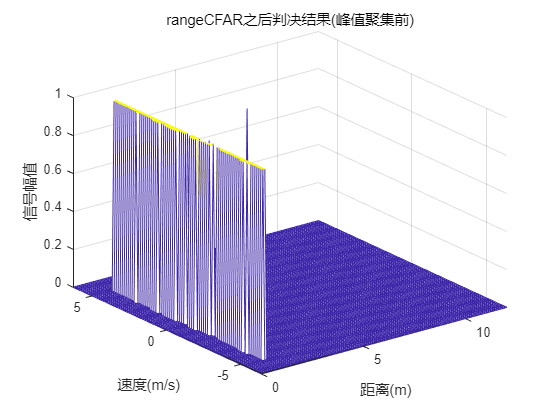


%% 速度维 CFAR
% %进行1D CFAR ，平均单元恒虚警率
% %缺点：多目标遮掩、杂波边缘性能欠佳
% %优点：损失率最小
% %参考单元：12
% %保护单元：2
% %虚警概率：
% %门限值：
Tv=6;Pv=4;PFAv=0.001;
Tr=6;Pr=4;PFAr=0.002;

dopplerDimCfarThresholdMap = zeros(size(FFT2_mag));  %创建一个二维矩阵存放doppler维cfar后的结果
dopplerDimCfarResultMap    = zeros(size(FFT2_mag));

for i=1:Range_Number
   dopplerDim =  reshape(FFT2_mag(:,i),1,Doppler_Number);  %变成一行数据
   [cfar1D_Arr,threshold] = ac_cfar1D(Tv,Pv,PFAv,dopplerDim);  %进行1D cfar
   dopplerDimCfarResultMap(:,i) = cfar1D_Arr.'; 
   dopplerDimCfarThresholdMap(:,i) = threshold.';
end

%% 距离维 CFAR
%沿着doppler维度方向寻找在doppler维cfar判决后为1的结果
saveMat = zeros(size(FFT2_mag));
for range = 1:Range_Number
    indexArr = find(dopplerDimCfarResultMap(:,range)==1);
    objDopplerArr = [indexArr;zeros(Doppler_Number - length(indexArr),1)];   %补充长度
    saveMat(:,range) = objDopplerArr; %保存doppler下标
end
% 保存有物体的doppler坐标
objDopplerIndex = unique(saveMat);  % unqiue是不重复的返回数组中的数

% 根据之前doppler维的cfar结果对应的下标saveMat，对相应的速度进行range维度的CFAR
rangeDimCfarThresholdMap = zeros(size(FFT2_mag));  %创建一个二维矩阵存放range维cfar后的结果
rangeDimCfarResultMap = zeros(size(FFT2_mag));
i = 1;
while(i<=length(objDopplerIndex))
    if(objDopplerIndex(i)==0)   % 因为数组里面有0,防止下面j取到0
        i = i + 1;
        continue;
    else    %根据速度下标进行range CFAR
        j = objDopplerIndex(i);     % 获得物体所在的行
        rangeDim = reshape(FFT2_mag(j, :),1,Range_Number);  %变成一行数据      
        [cfar1D_Avv,threshold] = ac_cfar1D(Tr,Pr,PFAr,rangeDim);  %进行1D cfar
        rangeDimCfarResultMap(j,:) = cfar1D_Avv; 
        rangeDimCfarThresholdMap(j,:) = threshold;
        i = i + 1;   
    end
end
figure(4);
mesh(X,Y,(rangeDimCfarResultMap));
xlabel('距离(m)');ylabel('速度(m/s)');zlabel('信号幅值');
title('rangeCFAR之后判决结果(峰值聚集前)');
xlim([0     Params.c*(Params.NSample-1)*Params.Fs/2/Params.freqSlope/Params.NSample]);
ylim([(-Params.NChirp/2)*Params.lambda/Params.Tc/Params.NChirp/2    (Params.NChirp/2 - 1)*Params.lambda/Params.Tc/Params.NChirp/2]);

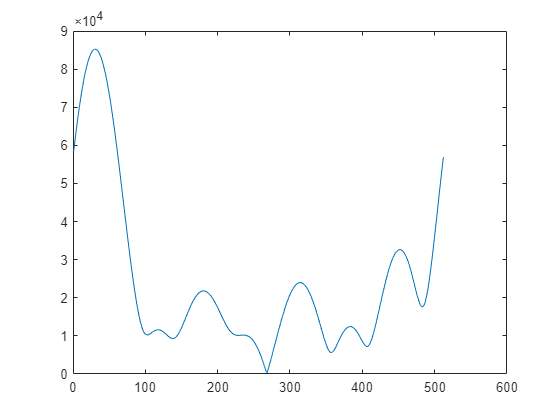

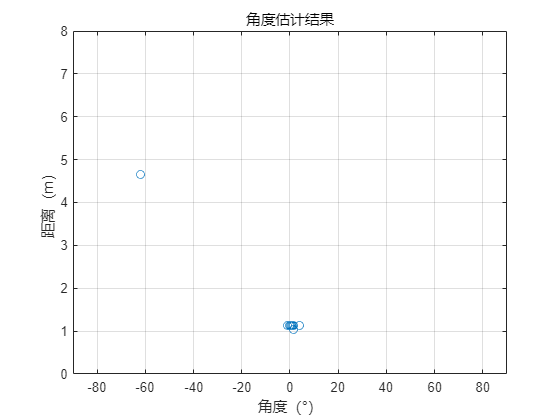

   
%% 对目标进行 角度维 FFT
%% 峰值检索
[objDprIdx,objRagIdx] = peakFocus(rangeDimCfarResultMap);%距离和速度的ID号

objDprIdx(objDprIdx==0)=[]; %去掉后面的0
objRagIdx(objRagIdx==0)=[];

%% 计算目标距离、速度，输出
objSpeed = ( objDprIdx - Params.NChirp/2 - 1)*Params.lambda/Params.Tc/Params.NChirp/2;
objRange = single(Params.c*(objRagIdx-1)*Params.Fs/2/Params.freqSlope/Params.NSample);

%如果有目标则进行角度FFT
if(~isempty(objDprIdx))
    angle =processingChain_angleFFT(objDprIdx,objRagIdx,fft2d);
    figure(5);
    plot(angle,objRange,'o')
    grid on;
    rlim = 8;
    axis([-90/rlim 90/rlim 0 1]*rlim);
    title('角度估计结果');
    ylabel('距离（m）');
    xlabel('角度（°）')   
end

function [cfar1D_Arr,threshold] = ac_cfar1D(NTrain,NGuard,PFA,inputArr)
%% 功能函数
    cfar1D_Arr = zeros(size(inputArr));
    threshold = zeros(size(inputArr));

    totalNTrain = 2*(NTrain);
    a = totalNTrain*((PFA^(-1/totalNTrain))-1);
    %求平均值
    for i = NTrain+NGuard+1:length(inputArr)-NTrain-NGuard
        avg = mean([inputArr((i-NTrain-NGuard):(i-NGuard-1))   inputArr((i+NGuard+1):(i+NTrain+NGuard))]);
        threshold(1,i) = a.*avg;
        %根据threshold比较
        if(inputArr(i) < threshold(i))
            cfar1D_Arr(i) = 0;
        else
            cfar1D_Arr(i) = 1;
        end
    end
    
end

%% 功能函数 
function [cfar1D_Arr,threshold] = ac_cfar2D(NTrain,NGuard,PFA,inputArr)
    cfar1D_Arr = zeros(size(inputArr));
    threshold = zeros(size(inputArr));

    totalNTrain = 2*(NTrain);
    a = totalNTrain*((PFA^(-1/totalNTrain))-1);
    %求平均值
    for i = NTrain+NGuard+1:length(inputArr)-NTrain-NGuard
        avg = mean([inputArr((i-NTrain-NGuard):(i-NGuard-1))   inputArr((i+NGuard+1):(i+NTrain+NGuard))]);
        threshold(1,i) = a.*avg;
        %根据threshold比较
        if(inputArr(i) < threshold(i))
            cfar1D_Arr(i) = 0;
        else
            cfar1D_Arr(i) = inputArr(i);
        end
    end
    
end

% 输入: inputCfarResMat - 进行峰值聚焦的二维矩阵,即进行range维CFAR判决后得到的结果矩阵
% 输出: row - 物体的行坐标(对应速度)
% column - 物体的列坐标(对应距离)
function [row,column] = peakFocus(inputCfarResMat)
    global FFT2_mag;
    j = 1;
    row = zeros([1 256]);
    column = zeros([1 256]);
    [d,r] = find(inputCfarResMat==1);   %寻找进行range维cfar后的判决为1的坐标
    for i = 1 : length(d)
        peakRow = d(i);
        peakColumn = r(i);
        peak = FFT2_mag(peakRow,peakColumn);  %待验证的峰值
        % 在附近的3*3矩阵中的数进行比较,如果中间的数是最大值,就判定为1  tip:现在知道变量名太长的后果了 ┭┮﹏┭┮
        % 把附近的8+1个数取出来
        % 根据之前进行的2次cfar,因为有TrainCell和GuardCell，所以不会碰到边缘
        tempArr =[FFT2_mag(peakRow-1,peakColumn-1) , FFT2_mag(peakRow-1,peakColumn) ,  FFT2_mag(peakRow-1,peakColumn+1), ...
                  FFT2_mag(peakRow,peakColumn-1)   ,                     peak                             , FFT2_mag(peakRow,peakColumn+1), ...
                  FFT2_mag(peakRow+1,peakColumn-1) , FFT2_mag(peakRow+1,peakColumn) ,  FFT2_mag(peakRow+1,peakColumn+1)] ;    
        truePeak = max(tempArr);     % 寻找最大值
        if(truePeak == peak)         %如果中间的是最大值就保存当前的坐标
            row(j) = peakRow;
            column(j) = peakColumn;
            j = j+1;
        end
    end
end

 function [sphandle] = configureDataSport(comPortString, bufferSize)
  
%     comPortString = ['COM' num2str(comPortNum)];
    sphandle = serial(comPortString,'BaudRate',921600);
%     set(sphandle,'Timeout',15);
    set(sphandle,'Terminator', '');
    set(sphandle,'InputBufferSize', bufferSize);
    set(sphandle,'Timeout',10);
    set(sphandle,'ErrorFcn',@dispError);
    fopen(sphandle);
 end
    
    function [sphandle] = configureControlPort(comPortString)
    %if ~isempty(instrfind('Type','serial'))
    %    disp('Serial port(s) already open. Re-initializing...');
    %    delete(instrfind('Type','serial'));  % delete open serial ports.
    %end
    %comPortString = ['COM' num2str(comPortNum)];
    sphandle = serial(comPortString,'BaudRate',115200);
    set(sphandle,'Parity','none')    
    set(sphandle,'Terminator','LF')        
    fopen(sphandle);
    end
    
    function config = readCfg(filename)  %读取配置文件
    config = cell(1,100);
    fid = fopen(filename, 'r');
    if fid == -1
        fprintf('File %s not found!\n', filename);
        return;
    else
        fprintf('Opening configuration file %s ...\n', filename);
    end
    tline = fgetl(fid);
    k=1;
    while ischar(tline)
        config{k} = tline;
        tline = fgetl(fid);
        k = k + 1;
    end
    config = config(1:k-1);
    fclose(fid);
    end
    
    function [angle] = processingChain_angleFFT(objDprIndex,objRagIndex,fft2d)

    angleFFTNum = 512;
    NObject = length(objDprIndex);  %检测的物体数目,点迹
  
    %初始化一个二维数组存放FFT结果
    angleFFTOut = single(zeros(NObject,angleFFTNum));
    for i=1:NObject
        
        %%
        frameData(1,:) = fft2d(objDprIndex(i),objRagIndex(i),:);  
        frameFFTData = fftshift(fft(frameData, angleFFTNum));      %进行NChan点的angler-FFT
                                                                   %fftshift移动零频点到频谱中间  不是很懂
                                                                   %有+Π 和 -Π     
        angleFFTOut(i,:) = frameFFTData(1,:);   %把FFT的结果放入angleFFTOut
        plot(abs(angleFFTOut(i,:)));
        
        maxIndex= find(abs(angleFFTOut(i,:))==max(abs(angleFFTOut(i,:))));
        angle (i)= asin((maxIndex - angleFFTNum/2 - 1)*2/angleFFTNum) * 180/pi;

    end  
    end
% 调皮连续波
function [userport, dataport] = serial_port()

port =IdentifySerialComs();

user_flag = 1;
data_flag = 1;

for i = 1:length(port)
    if(user_flag)
        userportID = find(strcmp('XDS110 Class Application/User UART',  port(i,1)));        
        if(userportID)
            user_flag = 0;
            userport = port(i,2);
        end 
        
    end
    
    if(data_flag)     
        dataportID = find(strcmp('XDS110 Class Auxiliary Data Port',  port(i,1)));
        if(dataportID)
               data_flag = 0;
               dataport = port(i,2);
        end
    end  
end

userport = ['COM',num2str(cell2mat(userport))];
dataport = ['COM',num2str(cell2mat(dataport))];

end

function devices = IdentifySerialComs()

devices = [];

Skey = 'HKEY_LOCAL_MACHINE\HARDWARE\DEVICEMAP\SERIALCOMM';

[~, list] = dos(['REG QUERY ' Skey]);
if ischar(list) && strcmp('ERROR',list(1:5))  %% strcmp 两个字符串相同返回1
    disp('Error: EnumSerialComs - No SERIALCOMM registry entry')
    return;
end

list = strread(list,'%s','delimiter',' '); %#ok<FPARK> requires strread()
coms = 0;

for i = 1:numel(list)  %%numel 返回元素个数
    if strcmp(list{i}(1:3),'COM')
        if ~iscell(coms)
            coms = list(i);
        else
            coms{end+1} = list{i}; %#ok<AGROW> Loop size is always small
        end
    end
end

out = 0;
outK = 0;

for j=1:2
    switch j
        case 1
            key = 'HKEY_LOCAL_MACHINE\SYSTEM\CurrentControlSet\Enum\USB\';
        case 2
            key = 'HKEY_LOCAL_MACHINE\SYSTEM\CurrentControlSet\Enum\FTDIBUS\';
    end
    [~, vals] = dos(['REG QUERY ' key ' /s /f "FriendlyName" /t "REG_SZ"']);
    if ischar(vals) && strcmp('ERROR',vals(1:5))
        disp('Error: EnumSerialComs - No Enumerated USB registry entry')
        return;
    end
    vals = textscan(vals,'%s','delimiter','\t');
    vals = cat(1,vals{:});
    for i = 1:numel(vals)
        if strcmp(vals{i}(1:min(12,end)),'FriendlyName')
            if ~iscell(out)
                out = vals(i);
            else
                out{end+1} = vals{i}; %#ok<AGROW> Loop size is always small
            end
            if ~iscell(outK)
                outK = vals(i-1);
            else
                outK{end+1} = vals{i-1}; %#ok<AGROW> Loop size is always small
            end
        end
    end
end

i_dev=1;Sservices=[];
for i = 1:numel(coms)
    match = strfind(out,[coms{i},')']);
    ind = 0;
    for j = 1:numel(match)
        if ~isempty(match{j})
            ind = j;
            [~, sers] = dos(['REG QUERY "' outK{ind} '" /f "Service" /t "REG_SZ"']);
            sers = textscan(sers,'%s','delimiter','\t');
            sers = cat(1,sers{:});
            if (numel(sers)>1)
                sers=strread(sers{2},'%s','delimiter',' ');
                Sservices{i_dev} = sers{3};
                i_dev=i_dev+1;
            end
        end
    end
end
Sservices=unique(Sservices);

i_dev=1;
for ss=1:numel(Sservices)
    key = ['HKEY_LOCAL_MACHINE\SYSTEM\CurrentControlSet\services\' Sservices{ss} '\Enum'];
    [~, vals] = dos(['REG QUERY ' key ' /f "Count"']);
    if ischar(vals) && strcmp('ERROR',vals(1:5))
        %         disp('Error: EnumSerialComs - No Enumerated services USB registry entry')
        %         return
    end
    vals = textscan(vals,'%s','delimiter','\t');
    vals = cat(1,vals{:});

    if (numel(vals)>1)
        vals=strread(vals{2},'%s','delimiter',' ');
        Count=hex2dec(vals{3}(3:end));
        if Count>0
            [~, vals] = dos(['REG QUERY ' key]);
            vals = textscan(vals,'%s','delimiter','\t');
            vals = cat(1,vals{:});
            out=0;
            j=0;
            for i = 1:numel(vals)
                Enums=strread(vals{i},'%s','delimiter',' ');
                try nums=hex2dec(Enums{1});
                catch
                    nums=-1;
                end
                if(nums==j)
                    out=['HKEY_LOCAL_MACHINE\SYSTEM\CurrentControlSet\Enum\' Enums{3}];
                    [~, listC] = dos(['REG QUERY "' out '" /s /f "PortName" /t "REG_SZ"']);
                    listC = textscan(listC,'%s','delimiter','\t');
                    listC = cat(1,listC{:});
                    if (numel(listC)>1)
                        listC=strread(listC{2},'%s','delimiter',' ');
                        for i = 1:numel(coms)
                            if strcmp(listC{3},coms{i})
                                [~, NameF] = dos(['REG QUERY "' out '" /s /f "FriendlyName" /t "REG_SZ"']);
                                NameF = textscan(NameF,'%s','delimiter','\t');
                                NameF = cat(1,NameF{:});
                                com = str2double(coms{i}(4:end));
                                if com > 9
                                    length = 8;
                                else
                                    length = 7;
                                end
                                devices{i_dev,1} = NameF{2}(27:end-length); %#ok<AGROW>
                                devices{i_dev,2} = com; %#ok<AGROW> Loop size is always small
                                i_dev=i_dev+1;
                            end
                        end
                    end
                    j=j+1;
                end
            end
        end
    end
end

end